clearvars
Ns =2.^(1:12);
[a,z] = size(Ns);

errs = ones(1,z);
for j = 1:z
    
    N = Ns(j);
    h = 1/(N-1);
    time =0:h:1;
    


    U0 = 1;
    U1 =U0;
    Uevalution =ones(1,N);
    Uevalution(1)= U1;
    for i =2:N
        U1 = RK4(@f,time(i),U1,h);
        Uevalution(i) = U1;
    end
    Uexact =exp(time);
    errs(j) = max(abs(Uexact -Uevalution));

end

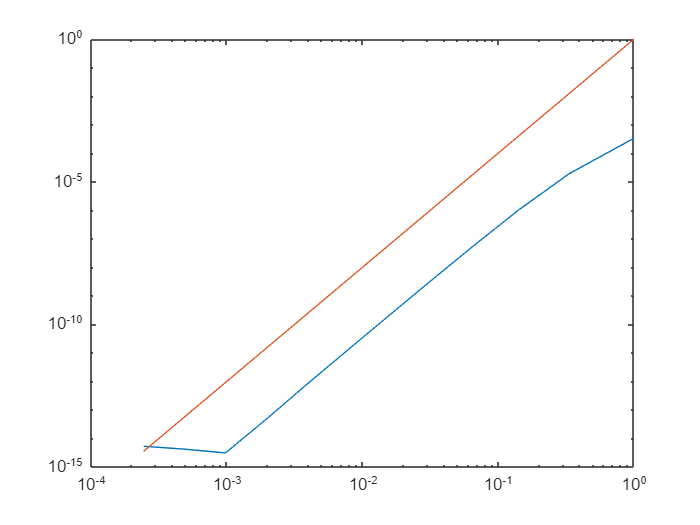


loglog(1./(Ns-1),errs); hold on
loglog(1./(Ns-1),(1./(Ns-1)).^4);
hold off

function res = f(t,x)
    res =x;
end
function res = RK4(f,t,u,h) % RK5
    k1 = f(t,u);
    k2 = f(t+1/4*h,u + 1/4*k1*h);
    k3 = f(t+3/8*h,u + 3/32*k1*h + 9/32*k2*h);
    k4 = f(t+12/13*h,u + 1932/2197*k1*h  - 7200/2197*k2*h + 7296/2197*k3*h);
    k5 = f(t+h,u + 439/216*k1*h - 8*k2*h + 3680/513*k3*h - 845/4104*k4*h);
    k6 = f(t+1/2,u - 8/27*k1*h + 2*k2*h - 3544/2565*k3*h + 1859/4104*k4*h - 11/40*k5*h);% need to check t+1/2 ??? mb t+1/2h??
    u_next = u + h*(25/216*k1 + 1408/2565*k3 + 2197/4104*k4 - 1/5*k5);
    %u_next = u + h*(16/135*k1 + 6656/12825*k3 + 28561/56430*k4 - 9/50*k5 + 2/55*k6);

    res = u_next;
end

function res = OptimalStep(f,t,u,tol,h,hmin,hmax)
    k1 = f(t,u);
    k2 = f(t+1/4*h,u + 1/4*k1*h);
    k3 = f(t+3/8*h,u + 3/32*k1*h + 9/32*k2*h);
    k4 = f(t+12/13*h,u + 1932/2197*k1*h  - 7200/2197*k2*h + 7296/2197*k3*h);
    k5 = f(t+h,u + 439/216*k1*h - 8*k2*h + 3680/513*k3*h - 845/4104*k4*h);
    k6 = f(t+1/2,u - 8/27*k1*h + 2*k2*h - 3544/2565*k3*h + 1859/4104*k4*h - 11/40*k5*h);% need to check t+1/2 ??? mb t+1/2h??
    u4_next = u + h*(25/216*k1 + 1408/2565*k3 + 2197/4104*k4 - 1/5*k5);
    u5_next = u + h*(16/135*k1 + 6656/12825*k3 + 28561/56430*k4 - 9/50*k5 + 2/55*k6);
    E = u5_next - u4_next;
    hnew = h*(tol/E)^(1/5);
    hopt = min(hmax,max(hmin,hnew));
    res = hopt;
end